# Markov Chains

## Using Matrices to represent Markov Chains

Markov chains are a collection of states with probabilities to go to the next state. Since these are probabilities, we need to make sure that each entry of each transition is between 0 and 1, and that the total of all transitions sums to exactly 1. A matrix that has these properties are called 'stochastic'. This is what motivates the code '*isStochastic(A)*', as it checks whether a given matrix is stochastic, and can be used to represent a Markov chain.

A = [1,0,0; 0,0.5,0.5; 0.1,0.4,0.5];
boolean = isStochastic(A)

boolean = logical
   1


doubleBool = isDoublyStochastic(A)

doubleBool = logical
   0


#### Visualizing Markov Chains

Nodes in the same communicating class have the same color. Solid markers represent nodes in recurrent classes, and hollow markers represent  nodes in transient classes. The legend contains the periodicity of  recurrent classes.

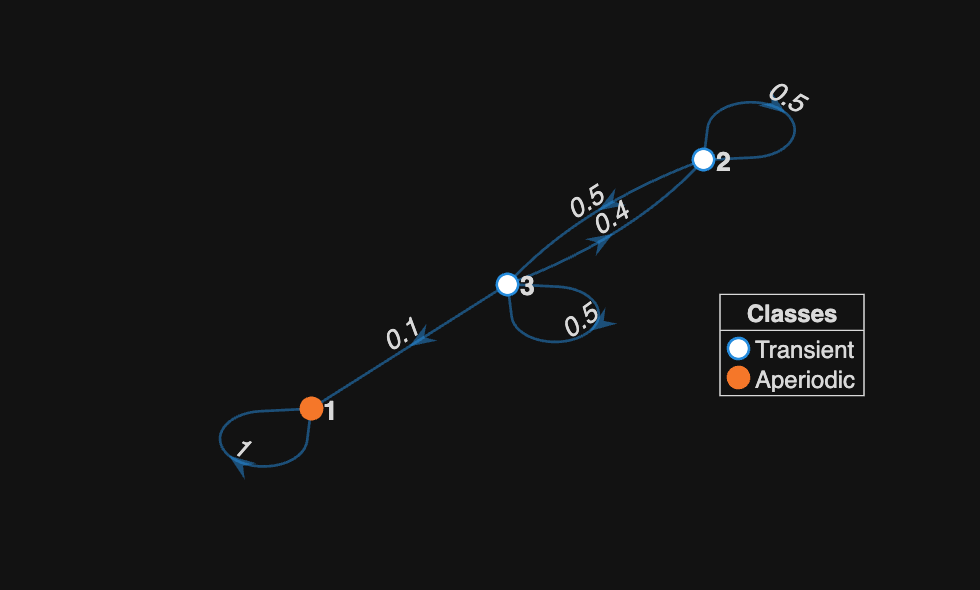

mc = dtmc(A);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

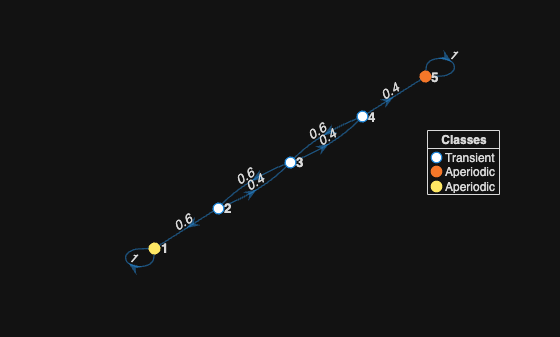

gamblersRuin = [1, 0, 0, 0, 0; 0.6, 0, 0.4, 0, 0; 0, 0.6, 0, 0.4, 0; 0, 0, 0.6, 0, 0.4; 0, 0, 0, 0, 1];
gamblersRuinMC = dtmc(gamblersRuin);
figure;
graphplot(gamblersRuinMC, 'LabelEdges', true, 'ColorNodes', true);

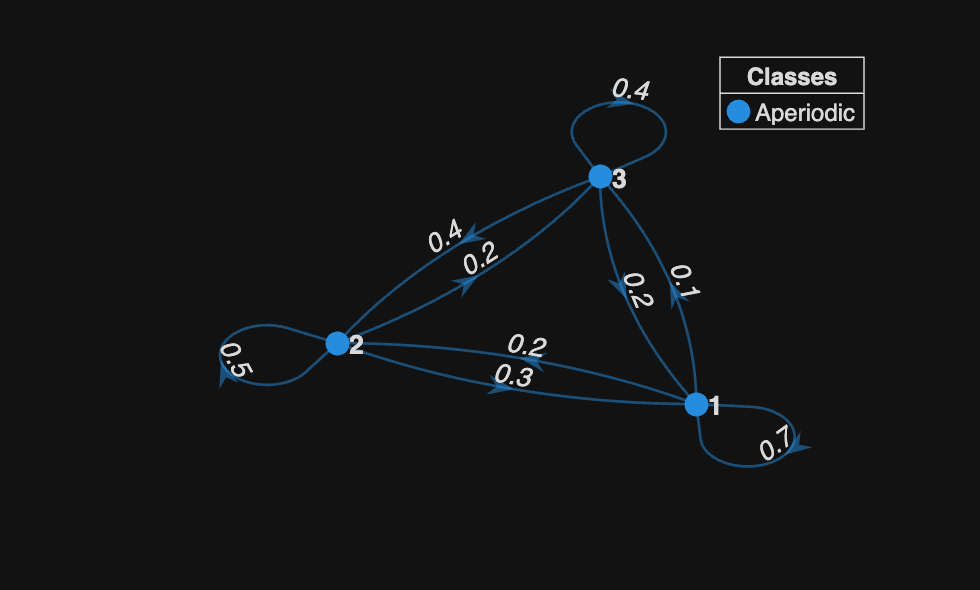

socialMobility = [0.7, 0.2, 0.1; 0.3, 0.5, 0.2; 0.2, 0.4, 0.4];
mc = dtmc(socialMobility);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

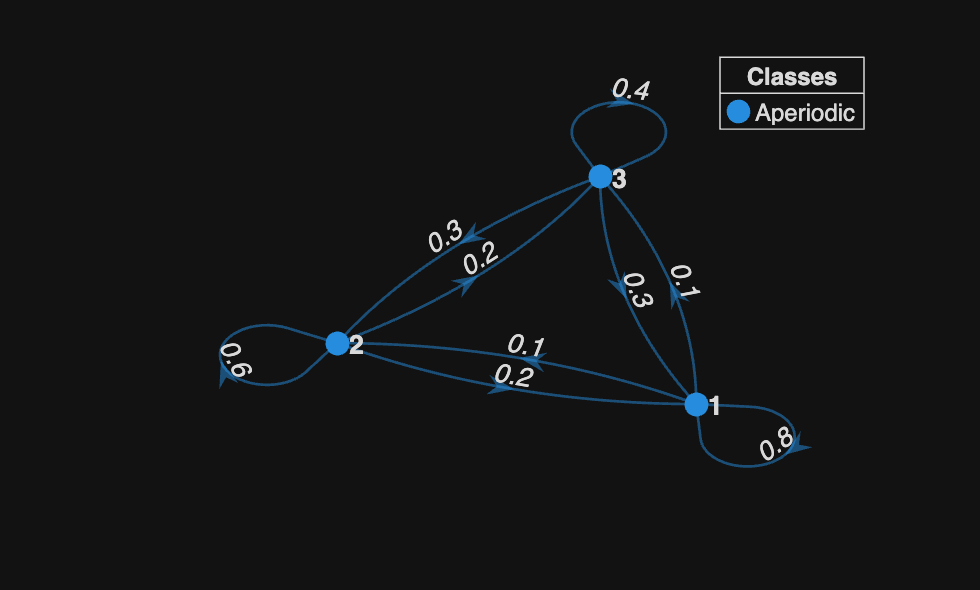

brandPref = [0.8, 0.1, 0.1; 0.2, 0.6, 0.2; 0.3, 0.3, 0.4];
mc = dtmc(brandPref);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

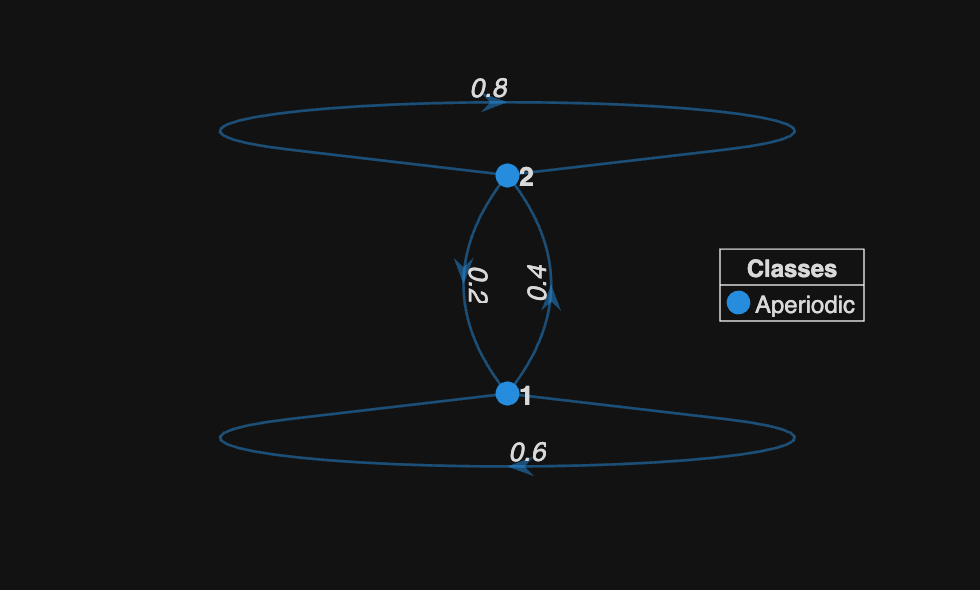

weather = [ 0.6, 0.4;0.2, 0.8];
mc = dtmc(weather);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

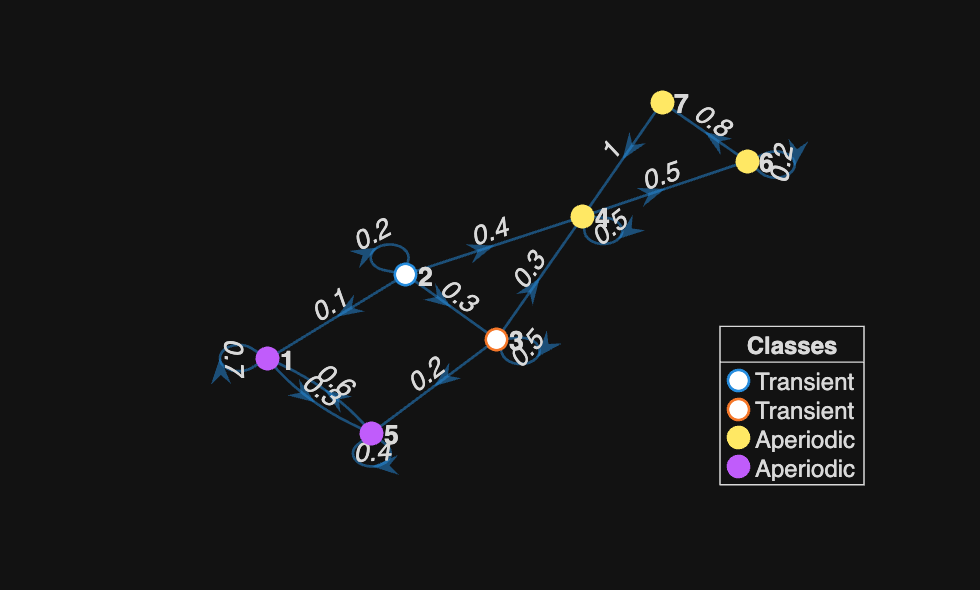

sevenStateChain = [0.7, 0, 0, 0, 0.3, 0, 0;
                   0.1, 0.2, 0.3, 0.4, 0, 0, 0;
                   0, 0, 0.5, 0.3, 0.2, 0, 0;
                   0, 0, 0, 0.5, 0, 0.5, 0;
                   0.6, 0, 0, 0, 0.4, 0, 0;
                   0, 0, 0, 0, 0, 0.2, 0.8;
                   0, 0, 0, 1, 0, 0, 0];
mc = dtmc(sevenStateChain);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

## Multistep Transitions

socialMobility = [0.7,0.2,0.1;0.3,0.5,0.2;0.2,0.4,0.4]

socialMobility =     0.7000    0.2000    0.1000
    0.3000    0.5000    0.2000
    0.2000    0.4000    0.4000


socialMobility2 = socialMobility^2

socialMobility2 =     0.5700    0.2800    0.1500
    0.4000    0.3900    0.2100
    0.3400    0.4000    0.2600


socialMobility2m = mpower(socialMobility,2)

socialMobility2m =     0.5700    0.2800    0.1500
    0.4000    0.3900    0.2100
    0.3400    0.4000    0.2600


socialMobility20 = socialMobility^20

socialMobility20 =     0.4681    0.3404    0.1915
    0.4681    0.3404    0.1915
    0.4681    0.3404    0.1915


statSocialMob = stationaryDistribution(socialMobility);
format rational
statSocialMob

statSocialMob =       22/47          16/47           9/47    


format rational

gamblersRuin2 = gamblersRuin^200

gamblersRuin2 =        1              0              0              0              0       
      57/65           *              0              *              8/65    
       9/13           0              *              0              4/13    
      27/65           *              0              *             38/65    
       0              0              0              0              1       


format rational
gamblersRuin1000 = gamblersRuin^1000

gamblersRuin1000 =        1              0              0              0              0       
      57/65           *              0              *              8/65    
       9/13           0              *              0              4/13    
      27/65           *              0              *             38/65    
       0              0              0              0              1       


format default

## Classification of States

## Stationary Distribution

A **stationary distribution** is a distribution $$\mathbf{\pi} = (\pi_1, \pi_2,\cdots, \pi_n)$$ (where $\pi_1 + \pi_2 + \cdots +\pi_n = 1$, after all it is a distribution) such that taking one more step through the transition matrix $p$, we end up with the same distribution as before, namely $\bf\pi$. This can be represented by $\mathbf{\pi} p = \mathbf{\pi}$. We will explain this concept through 2 and 3 state Markov chains, and then generalize to a method that works for any size Markov Chain.

#### Stationary Distribution for 2- state Markov Chain 

Recall the weather chain example. We would like to write it in the stationary distribution form. 


$$\mathbf{W} = \pmatrix{0.6 & 0.4  \cr 0.2 & 0.8 }$$



$$\pmatrix{\pi_1 & \pi_2}\pmatrix{0.6 & 0.4  \cr 0.2 & 0.8 } = \pmatrix{\pi_1 & \pi_2}$$


This means we get the following system of equations:


$$0.6\pi_1 + 0.2\pi_2 = \pi_1\\
0.4\pi_1 + 0.8\pi_2 = \pi_2$$


From high school algebra, we should be able to solve this as there are 2 equations and 2 unknowns. However, we observe that $\pi_1 = 0.5 \pi_2 $, so plugging into the second equation we get $\pi_2 = \pi_2$, so this is not the way to solve it. However, we also know that since both equations become $0.4\pi_1 = 0.2\pi_2 \Rightarrow 2\pi_1= \pi_2$, and $\pi_1+\pi_2 = 1$, then $\pi_1 = \frac{1}{3}, \pi_2 = \frac{2}{3}$.

Quickly checking our solution, we arrive at 


$$\pmatrix{\pi_1 & \pi_2}\pmatrix{0.6 & 0.4 \cr 0.2 & 0.8} = \pmatrix{\frac{1}{3} & \frac{2}{3}}\pmatrix{0.6 & 0.4 \cr 0.2 & 0.8} = \pmatrix{\frac{0.6}{3} +\frac{0.4}{3} & \frac{0.4}{3} + \frac{1.6}{3}} = \pmatrix{\frac{1}{3} & \frac{2}{3}} = \pmatrix{\pi_1 & \pi_2}\$$


statWeather = stationaryDistribution(weather)

statSocialMob =     0.4681    0.3404    0.1915


#### Gerealization to Stationary Distribution for 2-state Markov Chains

Now let's try to use this method to a general 2 state Markov chain, where the two states are "1" and "2". Let $a
$ be the probability of going from 1 to 2, and $b$ be the probability of going from 2 to 1. Since each row has to sum to 1, this means the general chain looks like


$$\matrix{& {\bf 1} & {\bf 2} \cr {\bf 1} & 1-a & a\cr{\bf 2} & b & 1-b}$$


Now to find the stationary distribution, we form the equations


$$\pmatrix{\pi_1 & \pi_2}\pmatrix{1-a &a  \cr b & 1-b } = \pmatrix{\pi_1 & \pi_2}$$



$$(1-a)\pi_1 + b\pi_2 = \pi_1\\
a\pi_1 + (1-b)\pi_2 = \pi_2$$


Since both equations simplify to $\pi_1 = \frac{b}{a}\pi_2$, we need to additionally inforce the $\pi_1 + \pi_2 = 1$condition to solve the systems. Using substitution, we arrive at 

$\frac{b}{a}\pi_2 + \frac{a}{a}\pi_2 = 1 \Rightarrow \pi_2 = \frac{a}{a+b}$, so $\pi_1 = \frac{b}{a+b}$.

Lastly, we check that this formula is consistent with the answer that we found for the weather chain problem. There $a = 0.4, b = 0.2$, so $\pi_1 = \frac{0.2}{0.4+0.2} = \frac{1}{3}$, and $\pi_2 = \frac{0.4}{0.4+0.2} = \frac{2}{3}$, which is consistent to what we found above.

#### Stationary Distribution for 3- state Markov Chain

Now we turn our attention to 3-state Markov chains, such as the social mobility problem.


$$0.7\pi_1 + 0.3\pi_2 + 0.2\pi_3 =\pi_1\\
0.2\pi_1 + 0.5\pi_2 + 0.4\pi_3 = \pi_2\\
0.1\pi_1+ 0.2\pi_2 + 0.4\pi_3 = \pi_3$$


But observe that if we add the equations together, since the columns come from a stochastic matrix, we get the redudant equation that $\pi_1 +\pi_2 +\pi_3 =\pi_1 +\pi_2 +\pi_3$, which will cause the system of equations to be unsolvable. So we need to change this to $\pi_1 +\pi_2 +\pi_3 =1$, since it is a probability distribution, and it must sum to 1.  This means that we get the following system of equations.


$$-0.3\pi_1 + 0.3\pi_2 + 0.2\pi_3 =0\\
0.2\pi_1 - 0.5\pi_2 + 0.4\pi_3 = 0\\
\pi_1+ \pi_2 + \pi_3 = 1$$


Now with the following 

statSocialMob = stationaryDistribution(socialMobility)
brandPref = [0.8,0.1,0.1;0.2,0.6,0.2;0.3,0.3,0.4];

statBrandPref =     0.5455    0.2727    0.1818


statBrandPref = stationaryDistribution(brandPref)

#### General Stationary Distribution for $n$- state Markov Chains (advanced topic)

This code works for stochastic matrices of any size, but why? One of the main topics in Linear Algebra is that of an eigenvalue /eigenvector pair. $\mathbf{A}v= \lambda v$, where $\lambda$ is the eigenvalue and $v$ is the eigenvector. However, we don't have something that looks like this, but upon transposing the equation, we have

$v^\top\mathbf{A}^\top = \lambda v^\top$.

Setting $\lambda = 1, v^\top = \mathbf{\pi}$, we arrive at $\mathbf{\pi} \mathbf{A}^\top = \mathbf{\pi}$, which is exactly the same as trying to find the stationary distribution for a stochastic matrix $\mathbf{A}^\top$. This means that we can use techiniques from linear algebra to solve for the stationary distribution.

[v,d]=eig(socialMobility')

v =     0.7678    0.8125    0.2326
    0.5584   -0.4760   -0.7941
    0.3141   -0.3366    0.5615


d =     1.0000         0         0
         0    0.4414         0
         0         0    0.1586


Note that MatLab chose different values for the eigenvectors than the ones we chose.   However, the ratio of v1,1 to v1,2 and the ratio of v2,1 to v2,2 are the same as our solution; the chosen  eigenvectors of a system are not unique, but the ratio of their elements is.  (MatLab chooses the values such that the sum of the squares of the elements of each eigenvector equals unity). However, with our case we choose it so that the sum of the elements of each eigenvector equals unity. This is the difference between $\|v\|_2=1$ (what MatLab does) and $\|v\|_1 = 1$, which is what we need.

#### Convergence to Stationary Distribution

Why is it that sometimes we have $\lim_{n\to\infty} p^n(x,y) = \pi(y)$? Well, if we think about it, by applying more and more steps $n$, we will get pushed into the average over all transitions taking $n$ steps. For example, if there is a (set of) recurent states, odds are you will have taken many steps to be in this cycle and 

Power iteration.

Convergence to largest eigenvalue

We notice that with power iteration, we always converge to the highest eigenvalue, but we need to converge to the eigenvalue corresponding to 1. First it is important to show that 1 is always an eigenvalue of a stochastic matrix.

Let $\mathbf{A}$ be a stochastic matrix, so its rows sum to 1. By definition, an eigenvalue/ eigenvector pair for a matrix $\mathbf{A}$ is a $(\lambda, v)$ such that $\mathbf{A}v = \lambda v$. Observe that if $v = (1, 1, \cdots, 1)^\top$, then $\lambda = 1$would satisfy. Since we know that each row sums to one, then adding each element together will get us 1 for each row. This means $\mathbf{A}v = v$, which implies that $\lambda_{\text{max}} = 1$. 

Now that we know that $\lambda=1$ is an eigenvalue, why do we know that power iteration will always converge to this value. The answer is quiet simple once we know this one theorem.

Theorem 1.1 (Perron-Frobenius). Let $\mathbf{B}$ be an $n \times n$ matrix with nonnegative real

entries (i.e. $(\mathbf{B})_{ij}> 0, \forall i,j = 1,2,\cdots,n$). Then we have the following:

- $\mathbf{B}$ has a nonnegative real eigenvalue. The largest such eigenvalue, $\lambda(\mathbf{B})$, dominates the absolute values of all other eigenvalues of $\mathbf{B}$. The domination is strict if the entries of B are strictly positive.

- If $\mathbf{B}$ has strictly positive entries, then $\lambda(\mathbf{B})$ is a simple positive eigenvalue, and the corresponding eigenvector can be normalized to have strictly positive entries.

- If $\mathbf{B}$ has an eigenvector $v$ with strictly positive entries, then the corresponding eigenvalue $\lambda v$ is $\lambda(\mathbf{B})$.

From this theorem, we know that there has to exist a unique nonnegative, real eigenvalue that is bigger than all others. This means doing power iteration will converge to this eigenvalue. 

The Perron–Frobenius eigenvalue satisfies the inequalities 


$$\min_{i}\sum_j b_{ij} \leq r\leq \max_{i}\sum_j b_{ij}$$


However, in this setting of Stochastic matrices, we know that by summing over the columns, we will only have equality to 1, so $\min_i 1 \leq r\leq \max_i 1 = 1$. This means that I, A, S  and $p^n(x,y)$converges to the stationary distribution, then power method will converge.

[ev, evec] = powerIter(brandPref', 1,100)

ev = 1

evec =     0.5455
    0.2727
    0.1818


### Appendix 1: Function Codes for above

#### Checks if Matrix is a stochastic matrix

function bool = isStochastic(A)
    num_rows = size(A,1);   % Number of rows
    num_cols = size(A,2);   % Number of columns
    % Ensure A is square
    if num_cols ~= num_rows
        bool = false;
        return;
    end
    for i = 1:num_rows
        row_sum = 0;
        % Loop over columns of ith row
        for j = 1:num_cols
            % Checks for positive numbers 
            if A(i,j) < 0
                bool = false;
                return;
            else
                row_sum = row_sum + A(i,j);
            end
        end
        % Checks row sum adds to 1
        if row_sum ~= 1
            bool = false;
            return;
        end
    end
    bool = true;
end

#### Checks if Matrix is a doubly stochastic matrix

function bool = isDoublyStochastic(A)
    if (isStochastic(A) && isStochastic(A'))
        bool = true;
    else 
        bool = false;
    end
end


#### Solves the Stationary distribution of a matrix

function statDist = stationaryDistribution(A)
    n = size(A,1);
    A = A - eye(n); % pi P = pi I so pi (P-I) = 0
    A(:,n) = ones(1,n); % rewriting the last equation as pi_1 + pi_2 + pi_3 = 1
    lastRow = zeros(1,n);
    lastRow(n) = 1;
    % Solves (0,0,...,0,1)P^{-1} in a more efficient way
    statDist = lastRow/A;
end

#### Power Iteration Method

function [eval, evec] = powerIter(A,rank, niter)
    n = size(A,1);
    v = rand(n,rank);
    Av = A * v;
    Av = Av/norm(Av,1);
    for i = 1 : niter
        Av = A * Av;
        normAv = norm(Av,1);
        Av = Av/normAv;
    end

    evec = Av;
    eval = Av' * (A* Av) / (Av' * Av);
end